# Globals

freqPoints = [250, 500, 1000, 2500, 5000]; % Use for generating graphs
freqPoints_STD = logspace(log10(100), log10(20000), 200); % Use for
% generating Std Dev
freqPointsStr = {'250', '500', '1000', '2500', '5000'};

numSpeakers = 9;

theta = linspace(0-pi/10,2 * pi -pi/10,72); % HOA Mic rotation correction

% theta = linspace(0,2 * pi,72); % Airpods Mic rotation correction

r = linspace(1, 180, 180);

## Setup Vars

filePath = "/Users/johnwallar/Desktop/Projects/00 THESIS/Take 1 HOA/HOA Cleaning take 2/Bounced Files/"

filePath = "/Users/johnwallar/Desktop/Projects/00 THESIS/Take 1 HOA/HOA Cleaning take 2/Bounced Files/"

% filePath = "/Users/johnwallar/Desktop/Projects/00 THESIS/Take 2 Airpods/Cleaning/Bounced Files/"
Subfolder = "Card6"

Subfolder = "Card6"

alg_title = '2nd Order HOA MaxRe';
extension = '*.wav';

% ---------------------------------------------------

% Specify the folder containing the audio files
folderPath(1) = filePath + Subfolder + "/Sp1"; 
filePattern(1) = fullfile(folderPath(1), extension);

folderPath(2) = filePath + Subfolder + "/Sp2";
filePattern(2) = fullfile(folderPath(2), extension); 

folderPath(3) = filePath + Subfolder + "/Sp3"; 
filePattern(3) = fullfile(folderPath(3), extension); 

folderPath(4) = filePath + Subfolder + "/Sp4"; 
filePattern(4) = fullfile(folderPath(4), extension); 

folderPath(5) = filePath + Subfolder + "/Sp5"; 
filePattern(5) = fullfile(folderPath(5), extension);

folderPath(6) = filePath + Subfolder + "/Sp6"; 
filePattern(6) = fullfile(folderPath(6), extension); 

folderPath(7) = filePath + Subfolder + "/Sp7"; 
filePattern(7) = fullfile(folderPath(7), extension); 

folderPath(8) = filePath + Subfolder + "/Sp8"; 
filePattern(8) = fullfile(folderPath(8), extension); 

folderPath(9) = filePath + Subfolder + "/Sp9"; 
filePattern(9) = fullfile(folderPath(9), extension); 

audioFiles = [dir(filePattern(1)),dir(filePattern(2)),dir(filePattern(3)),dir(filePattern(4)),dir(filePattern(5)),dir(filePattern(6)),dir(filePattern(7)),dir(filePattern(8)),dir(filePattern(9))];

length(audioFiles)

ans = 72

## FFT

% Initialize storage array
magnitudeValues = zeros(length(audioFiles), length(freqPoints), numSpeakers);
magnitudeValues_STD = zeros(length(audioFiles), length(freqPoints_STD), numSpeakers);

% Loop through each audio file
for i = 1:numSpeakers % For Each Speaker
    for k = 1:length(audioFiles(:, i))
        % Read the audio file
        fileName = fullfile(folderPath(i), audioFiles(k, i).name);
        % disp("read " + fileName)
        [y, Fs] = audioread(fileName);
    
        % Convert stereo to mono if necessary
        if size(y, 2) > 1
            y = mean(y, 2); % Convert to mono by averaging channels
        end
    
        % Perform FFT
        N = length(y);
        Y = fft(y);
        f = (0:N-1) * (Fs/N); % Frequency vector

        % Extract magnitude values at specific frequencies
        for j = 1:length(freqPoints)
            [~, idx] = min(abs(f - freqPoints(j))); % Find closest frequency index
            magnitudeValues(k, j, i) = abs(Y(idx)); % Store magnitude
        end
        for j = 1:length(freqPoints_STD)
            [~, idx] = min(abs(f - freqPoints_STD(j))); % Find closest frequency index
            magnitudeValues_STD(k, j, i) = abs(Y(idx)); % Store magnitude
        end
    end
    disp("Completed speaker " + i)
end

Completed speaker 1
Completed speaker 2
Completed speaker 3
Completed speaker 4
Completed speaker 5
Completed speaker 6
Completed speaker 7
Completed speaker 8
Completed speaker 9



disp("+---------------+")

+---------------+


disp("|   FFT Done!   |")

|   FFT Done!   |


disp("+---------------+")

+---------------+


disp("")
disp("Now Normalizing and converting to dB")

Now Normalizing and converting to dB



magnitudeValues2 = magnitudeValues;
magnitudeValues_STD2 = magnitudeValues_STD;

% Uncomment the next two lines when running non-control datasets
% magnitudeValues2 = magnitudeValues ./ AP_OFF_mag;
% magnitudeValues_STD2 = magnitudeValues_STD ./ AP_OFF_mag_STD;

% Normalize magnitudes for better visualization in polar plot
normalizedValues = magnitudeValues2 ./ max(magnitudeValues2(:,:,5), [], 'all');
normalizedValues_STD = magnitudeValues_STD2 ./ max(magnitudeValues_STD2, [], 'all');

mag_dB = 20 * log10(normalizedValues + 1e-6);
mag_dB = max(mag_dB, -60); % Clip at -60 dB

mag_dB_STD = 20 * log10(normalizedValues_STD + 1e-6);
mag_dB_STD = max(mag_dB_STD, -60); % Clip at -60 dB

disp("+-------------------+")

+-------------------+


disp("| Normalizing Done! |")

| Normalizing Done! |


disp("+-------------------+")

+-------------------+


disp("")
disp(Subfolder)

Card6


beep on;
beep;

## Store AP_OFF

% Run this code section when doing the control
% This will store the values of the control to act as an HRTF to be divided
% by.
AP_OFF_mag = magnitudeValues;
AP_OFF_mag_STD = magnitudeValues_STD;

## Graphs By Frequency showing level distributions by Speaker

% Plot the polar graphs for each frequency

colors = lines(10);
for j = 1:length(freqPoints)
    figure; % Normal Figure
    polaraxes;
    hold on;
    for i = 1:numSpeakers
            polarplot(theta, mag_dB(:, j, i), '-', 'LineWidth', 2, 'Color', colors(i,:));
    end
    title(['Polar Plot of FFT Magnitude at ', num2str(freqPoints(j)), ' Hz Across All Speakers (dB)', newline, alg_title, ' Algorithm']);
    ax = gca;
    ax.ThetaZeroLocation = 'top';   % Set 0 degrees at the top
    ax.ThetaDir = 'counterclockwise'; % Ensure angles increase CCW

    rlim([-60, 0]); % dB range from -60 dB to 0 dB
    rticks([-60 -40 -20 0]); % Set dB tick marks

    legend({'Sp1', 'Sp2', 'Sp3', 'Sp4', 'Sp5', 'Sp6','Sp7', 'Sp8', 'Sp9'}, 'Location', 'best');
    hold off;
end

% Display the magnitude values for reference
% disp('Magnitude values at specified frequencies:');
% disp(magnitudeValues);


## Figure for Sp5 across Freq Bands

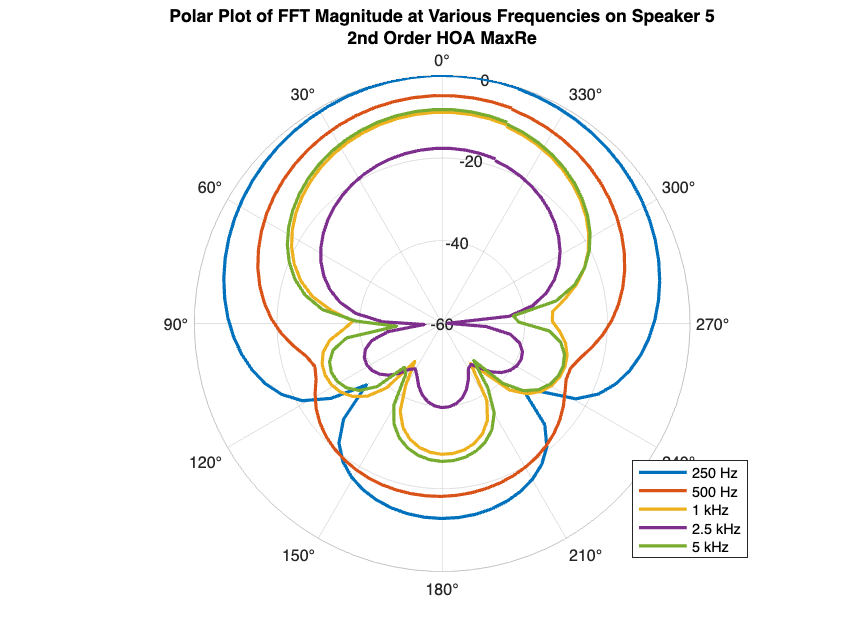

speaker = 5;

figure; % Normal Figure
polaraxes;
hold on;

colors = lines(10);

for j = 1:length(freqPoints)
        polarplot(theta, mag_dB(:, j, speaker), '-', 'LineWidth', 2, 'Color', colors(j,:));
end

title(['Polar Plot of FFT Magnitude at Various Frequencies on Speaker 5', newline, alg_title]);
ax = gca;
ax.ThetaZeroLocation = 'top';   % Set 0 degrees at the top
ax.ThetaDir = 'counterclockwise'; % Ensure angles increase CCW

rlim([-60, 0]); % dB range from -60 dB to 0 dB
rticks([-60 -40 -20 0]); % Set dB tick marks

legend({'250 Hz', '500 Hz', '1 kHz', '2.5 kHz', '5 kHz'}, 'Location', 'best');
hold off;

## Calc Standard Dev and HADI

PLW_Idx = (theta >= deg2rad(45)) & (theta <= deg2rad(315));
ALW_Idx = (theta < deg2rad(45)) | (theta > deg2rad(315));
CLW_Idx = (theta < deg2rad(30)) | (theta > deg2rad(330));
speech_range_Idx = (freqPoints_STD >= 200) & (freqPoints_STD <= 8000);

std500_PLW = std(mag_dB_STD(PLW_Idx, 2, speaker));
std5k_PLW = std(mag_dB_STD(PLW_Idx, 5, speaker));

for j = 1:length(freqPoints_STD)
    stdDev_ALW(j) = std(mag_dB_STD(ALW_Idx, j, speaker));
    stdDev_PLW(j) = std(mag_dB_STD(PLW_Idx, j, speaker));
    stdDev_tot(j) = std(mag_dB_STD(:, j, speaker));
        
end

% HADI_A
ALW_Bar = mean(mean(mag_dB_STD(ALW_Idx, speech_range_Idx, speaker)));
PLW_Bar = mean(mean(mag_dB_STD(PLW_Idx, speech_range_Idx, speaker)));
HADI_A = min(max(4 * (mean(ALW_Bar) - mean(PLW_Bar)), 0), 100)

HADI_A = 69.1103


% HADI_B
HADI_B = min(max(100 - ((6 * std(stdDev_ALW)) + (3 * std(stdDev_PLW)))))

HADI_B = 91.0210

## Plot Standard Dev

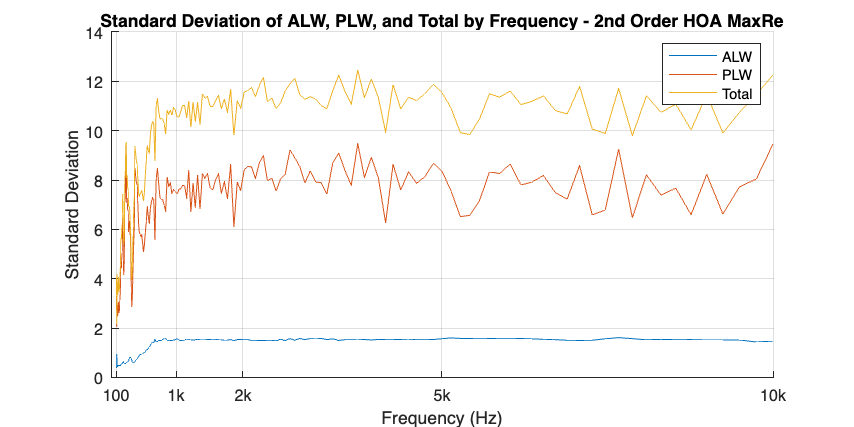

fig = figure;
set(fig, 'Position', [100, 100, 800, 400]);
hold on;

semilogx(freqPoints_STD, stdDev_ALW);
semilogx(freqPoints_STD, stdDev_PLW);
semilogx(freqPoints_STD, stdDev_tot);

legend({'ALW', 'PLW', 'Total'})
xlabel('Frequency (Hz)');
ylabel('Standard Deviation');
title(['Standard Deviation of ALW, PLW, and Total by Frequency - ', alg_title]);

grid on;
xlim([20 10000]);
xticks([100 1000 2000 5000 10000 20000]);  % Set custom tick positions
xticklabels({'100', '1k', '2k', '5k', '10k', '20k'});  % Set corresponding labels

hold off;

## Store for comparison graphs

% Uncomment a line to store the currently loaded data to compare with
% others in the following code blocks

% mag_dB_1 = mag_dB;
% mag_dB_2 = mag_dB;
% mag_dB_3 = mag_dB;
beep

## Table 1 - S. D. of Diff in Mag between 6th order and 2nd order by freqs in freqPoints

for j = 1:length(freqPoints)
    std(mag_dB_2(:, j, 5)-mag_dB_1(:, j, 5))
end

ans = 0.0077

ans = 0.0053

ans = 2.3571

ans = 7.0332

ans = 8.2622

## Comparing Algorithms

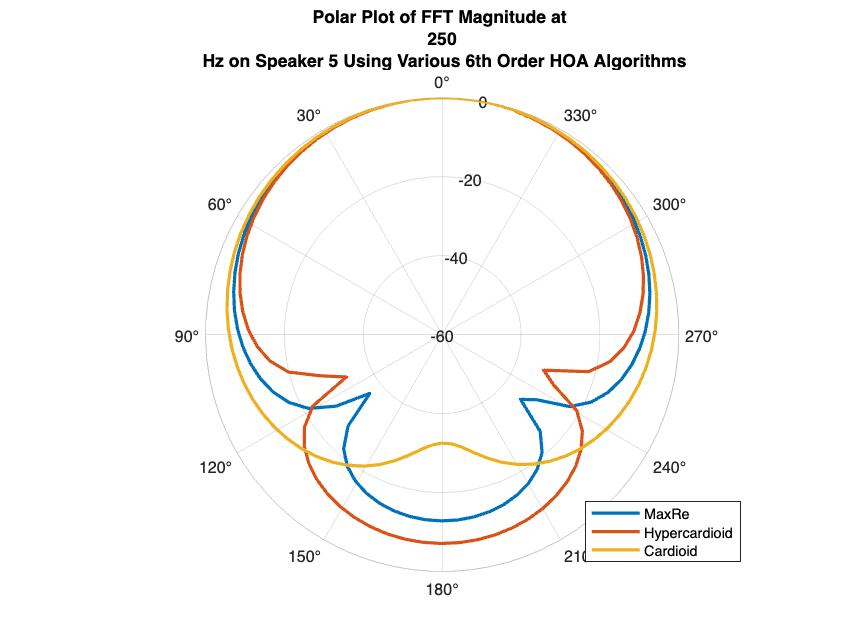

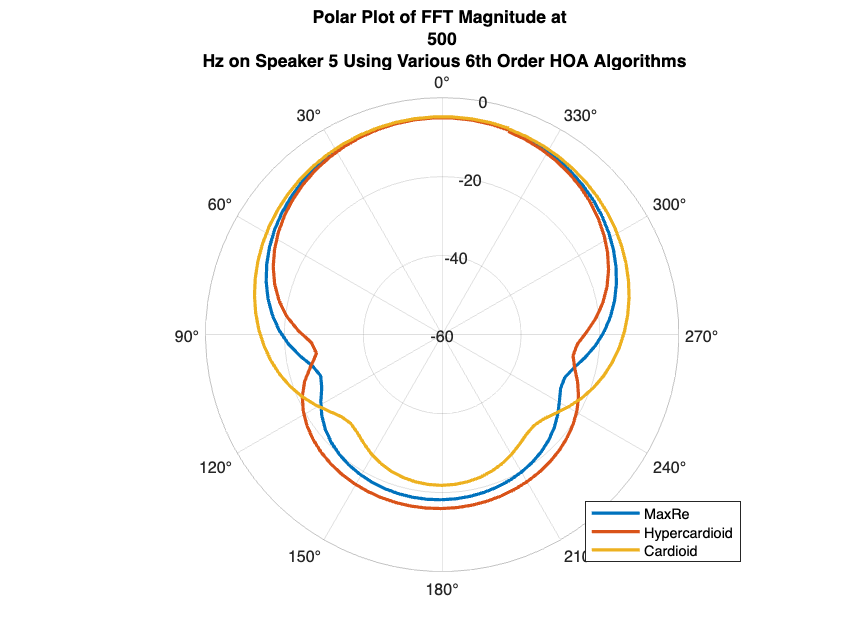

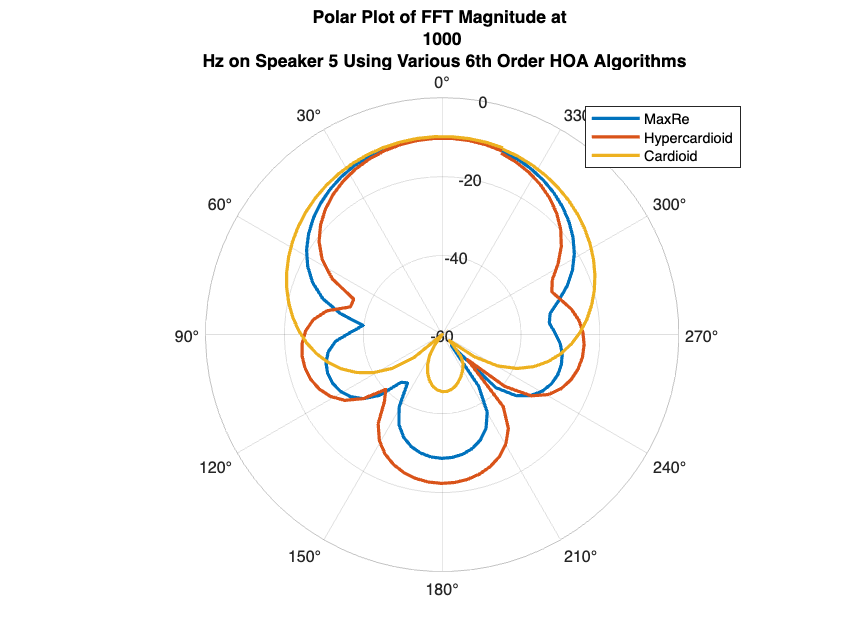

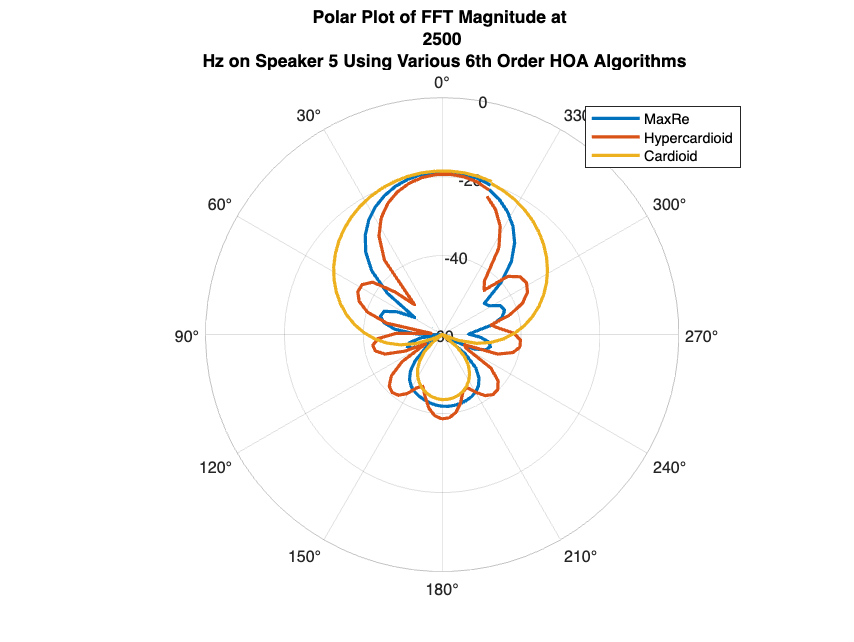

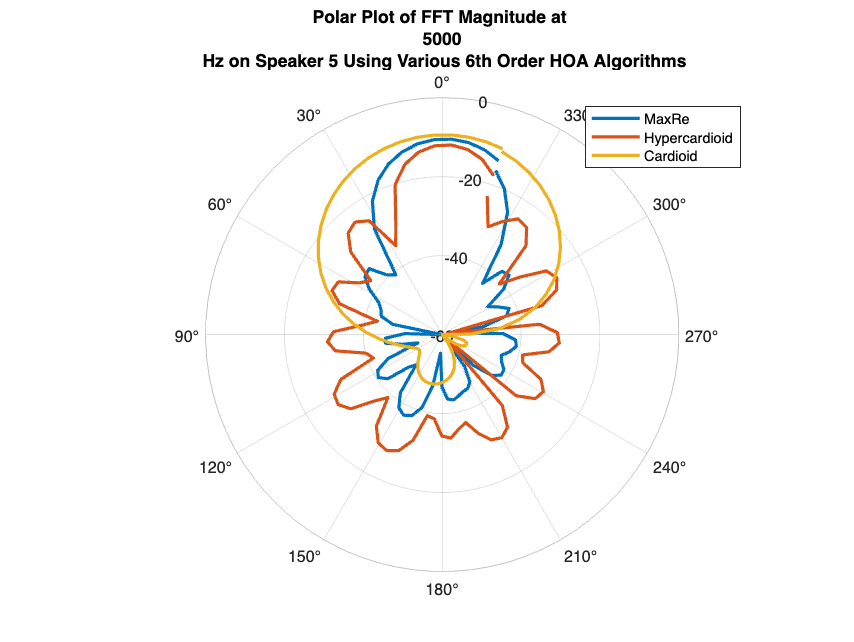

speaker = 5;

colors = lines(10);
for j = 1:length(freqPoints)
    figure; % Normal Figure
    polaraxes;
    hold on;
    % disp(['Polar Plot of FFT Magnitude at ', freqPointsStr(j), ' Hz on Speaker 5', 'using the ', alg_title, ' Algorithm'])
    polarplot(theta, mag_dB_1(:, j, speaker), '-', 'LineWidth', 2, 'Color', colors(1,:));
    polarplot(theta, mag_dB_2(:, j, speaker), '-', 'LineWidth', 2, 'Color', colors(2,:));
    polarplot(theta, mag_dB_3(:, j, speaker), '-', 'LineWidth', 2, 'Color', colors(3,:));
    
    title(['Polar Plot of FFT Magnitude at ', freqPointsStr(j), ' Hz on Speaker 5 Using Various 6th Order HOA Algorithms']);
    ax = gca;
    ax.ThetaZeroLocation = 'top';   % Set 0 degrees at the top
    ax.ThetaDir = 'counterclockwise'; % Ensure angles increase CCW

    rlim([-60, 0]); % dB range from -60 dB to 0 dB
    rticks([-60 -40 -20 0]); % Set dB tick marks

    legend({'MaxRe', 'Hypercardioid', 'Cardioid'}, 'Location', 'best');
    % legend({'6 Order Hyper', '4 Order Hyper', '6 Order Max Rej', '4 Ord Max Rej'}, 'Location', 'best');
    hold off;
end